## Task 2

% 2.a.
P = 100000;                               % Stopping criterion
C = 10;                                   % Link capacity in Mbps
lambda = 1500;                            % Values for packet rate in pps
f = 1000000;                              % Queue size(in bytes)
b = 10^-5;                                % Bit Error Rate

N = 20;                                   % number of simulation
n = [10, 20, 30, 40];                     % number of adidional VoIP packets flows

pkt_delay_voip = zeros(1, length(lambda));
error_delay_voip = zeros(1, length(lambda));
pkt_loss_voip = zeros(1, length(lambda)); 
error_loss_voip = zeros(1, length(lambda)); 

pkt_delay_data = zeros(1, length(lambda));
error_delay_data = zeros(1, length(lambda));
pkt_loss_data = zeros(1, length(lambda));  
error_loss_data = zeros(1, length(lambda));  

AVERAGE = zeros(4,4);
TERM = zeros(4,4);

for j = 1:length(n)
    PLd = zeros(1, N);
    PLv = zeros(1, N);
    APDd = zeros(1, N);
    APDv = zeros(1, N);
    MPDd = zeros(1, N);
    MPDv = zeros(1, N);
    TT = zeros(1, N);
    
    for i = 1:N
        [PLd(i), PLv(i), APDd(i), APDv(i), MPDd(i), MPDv(i), TT(i)] = Simulator3A(lambda,C,f,P,n(j), b);
    end    
    alfa = 0.1; % 90% confidence interval 
    
    
    AVERAGE = mean(PLd);
    TERM = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    fprintf("Packet Loss (%%)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss_data(j) = AVERAGE;
    error_loss_data(j) = TERM;

    AVERAGE = mean(APDd);
    TERM = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    fprintf("Av. Packet Delay Data (ms)  = %.2e +- %.2e\n\n\n", AVERAGE, TERM);
    pkt_delay_data(j) = AVERAGE;
    error_delay_data(j) = TERM;

    AVERAGE = mean(PLv);
    TERM = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    fprintf("Packet Loss VoIP (%%)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss_voip(j) = AVERAGE;
    error_loss_voip(j) = TERM;

    AVERAGE = mean(APDv);
    TERM = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    fprintf("Av. Packet Delay VoIP (ms)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_delay_voip(j) = AVERAGE;
    error_delay_voip(j) = TERM;
 
end

Packet Loss (%)  = 4.73e+00 +- 3.23e-02


Av. Packet Delay Data (ms)  = 2.15e+00 +- 2.10e-02




Packet Loss VoIP (%)  = 9.33e-01 +- 2.11e-02


Av. Packet Delay VoIP (ms)  = 1.75e+00 +- 2.02e-02


Packet Loss (%)  = 4.72e+00 +- 2.73e-02


Av. Packet Delay Data (ms)  = 2.69e+00 +- 3.88e-02




Packet Loss VoIP (%)  = 9.59e-01 +- 2.09e-02


Av. Packet Delay VoIP (ms)  = 2.28e+00 +- 3.67e-02


Packet Loss (%)  = 4.71e+00 +- 2.78e-02


Av. Packet Delay Data (ms)  = 3.55e+00 +- 7.55e-02




Packet Loss VoIP (%)  = 9.44e-01 +- 1.83e-02


Av. Packet Delay VoIP (ms)  = 3.14e+00 +- 7.12e-02


Packet Loss (%)  = 4.73e+00 +- 3.23e-02


Av. Packet Delay Data (ms)  = 5.71e+00 +- 1.81e-01




Packet Loss VoIP (%)  = 9.64e-01 +- 1.24e-02


Av. Packet Delay VoIP (ms)  = 5.30e+00 +- 1.74e-01


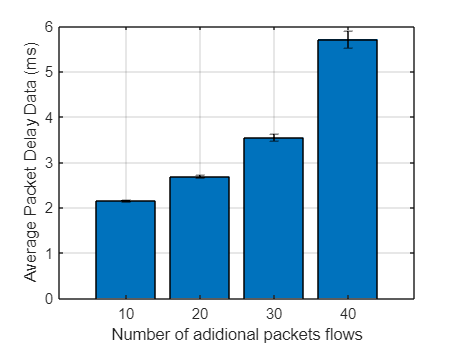



% Plot the results
figure(1)
bar(categorical(n), pkt_delay_data)
xlabel("Number of adidional packets flows")
ylabel("Average Packet Delay Data (ms)")
hold on
er = errorbar(categorical(n), pkt_delay_data, error_delay_data, error_delay_data);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

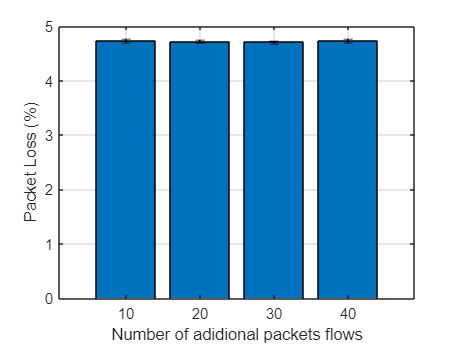


%%% Plot the results
figure(2)
bar(categorical(n), pkt_loss_data)
xlabel("Number of adidional packets flows")
ylabel("Packet Loss (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(n), pkt_loss_data, error_loss_data, error_loss_data);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

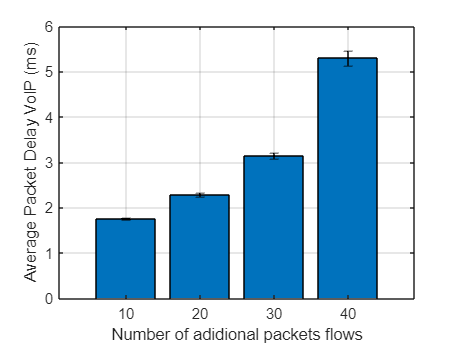


% Plot the results
figure(3)
bar(categorical(n), pkt_delay_voip)
xlabel("Number of adidional packets flows")
ylabel("Average Packet Delay VoIP (ms)")
hold on
er = errorbar(categorical(n), pkt_delay_voip, error_delay_voip, error_delay_voip);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

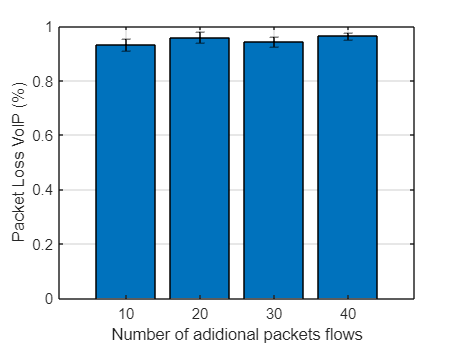


%%% Plot the results
figure(4)
bar(categorical(n), pkt_loss_voip)
xlabel("Number of adidional packets flows")
ylabel("Packet Loss VoIP (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(n), pkt_loss_voip, error_loss_voip, error_loss_voip);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

fprintf("-------------------------------------------")

-------------------------------------------